clearvars;
format shortG
xmin = -5;
xmax = 5;
ymin = -5;
ymax = 5;
zmin = 0;
zmax = 5;
xint = 1;
yint = 1;
zint = 1;
xtotal = ((xmax-xmin)/xint + 1);
ytotal = ((ymax-ymin)/yint + 1);
ztotal = ((zmax-zmin)/zint + 1);
%datasize = xtotal*ytotal*ztotal;

diameter = 3/16*25.4; %mm
height = 1/8*25.4; %mm
Br_max = 12100*0.1; %mT
mu_0 =  4*pi*10^-7*1000*1000; % mT mm/A^2
sensorheight = 20; %mm
%want M in A/m
M=Br_max;
B_t = pi*(diameter/2)^2*height*Br_max/(4*pi);
sensor_separation = 35; %mm

can unplug and check i2c.

Sensor locations:

Top left is 0

sensor 0: (0, 0)

sensor 1: (0, -35)

sensor 2: (35, -35)

sensor 3: (35,0)

sensors = [Sensor(0x1d, i2c_dev=1), Sensor(0x1e, i2c_dev=5), Sensor(0x1e, i2c_dev=1), Sensor(0x1d, i2c_dev=5)]

sensor_positions = np.array([[0., 0., 0.], [35., 0., 0.], [0., 35., 0.], [35., 35., 0.]])

% writematrix(dataavg, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\PIM04142023_dataavg');
% writematrix(location, 'C:\Users\Brandon Nguyen\OneDrive\Watanabe_Project\m6to6_m6to6_m6to6_0p2Increment.txt')

%location = [];
% z = zmin;
% dataavg = [];
% 
% for k = 1:ztotal
%     zstr = sprintf('%.1f', z);
%     y = ymin;
% 
%     for j = 1:ytotal
%         ystr = sprintf('%.1f', y);
%         x = xmin;
% 
%         for i = 1:xtotal
% 
%             xstr = sprintf('%.1f', x);
%             filename = append('C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\PIM05172023_contest3\',xstr,'_',ystr,'_',zstr,'.data');
%             test = importdata(filename);
%             
%             bx1 = test.data(1:99,6);
%             by1 = test.data(1:99,7);
%             bz1 = test.data(1:99,8);
% 
%             bx2 = test.data(100:199,6);
%             by2 = test.data(100:199,7);
%             bz2 = test.data(100:199,8);
% 
%             bx3 = test.data(200:299,6);
%             by3 = test.data(200:299,7);
%             bz3 = test.data(200:299,8);
%             
%             bx4 = test.data(300:399,6);
%             by4 = test.data(300:399,7);
%             bz4 = test.data(300:399,8);
%             dataavg = [dataavg 
%                 [mean(bx1) mean(by1) mean(bz1) mean(bx2) mean(by2) mean(bz2) mean(bx3) mean(by3) mean(bz3) mean(bx4) mean(by4) mean(bz4)]];
%             %location = [location
%                 %[x y z]];
%            
%             x = x + xint;
%         end
%         y = y + yint;
%     end
%     z = z + zint;
% end

% dataavg
% writematrix(dataavg, 'C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\contest3avg.txt')
% %writematrix(location, 'C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\m5to5_m5to5_0to5_1Increment.txt')

location = importdata('C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\m5to5_m5to5_0to5_1Increment.txt')

location =     -5    -5     0
    -4    -5     0
    -3    -5     0
    -2    -5     0
    -1    -5     0
     0    -5     0
     1    -5     0
     2    -5     0
     3    -5     0
     4    -5     0


con2 = importdata('C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\contest2avg.txt')

con2 =      0.014735     0.042796     0.026703    -0.037306     0.045668     0.021202     0.038993     -0.04037     0.046643    -0.046491    -0.017857     0.013888
     0.015057     0.042543     0.026241    -0.037368     0.045953     0.021592     0.039478    -0.040032     0.046297    -0.046677     -0.01819     0.014404
     0.015798     0.041844     0.025075    -0.037499     0.046741     0.022242     0.040423     -0.03929     0.045214    -0.047016    -0.018884      0.01562
     0.016976     0.040723     0.023235    -0.037601     0.048042     0.023643     0.041921    -0.038068     0.043542    -0.047352    -0.020115     0.017469
     0.018366     0.039328     0.021066    -0.037754      0.04968     0.025433     0.043616    -0.036565     0.041089    -0.047642    -0.021769     0.019896
     0.019273     0.038154     0.019263    -0.037784      0.05097     0.027017     0.044763    -0.035368     0.039322    -0.047893    -0.023051     0.021915
     0.020022     0.037025      0.01756    -0.03776

con3 = importdata('C:\Users\Brandon Nguyen\Desktop\Watanabe_Project\contest3avg.txt')

con3 =      0.015436     0.042665     0.026065    -0.037309     0.046406     0.021052     0.040039    -0.039997     0.045918    -0.046908    -0.018267     0.014897
     0.016082     0.042279     0.024959    -0.037395     0.047138      0.02171     0.040969     -0.03948     0.045165    -0.047238    -0.019011     0.015922
     0.016551     0.041849     0.024254    -0.037506     0.047677     0.022294     0.041546    -0.039009     0.044526    -0.047418    -0.019521     0.016646
     0.017032     0.041307     0.023396    -0.037682     0.048365     0.022929     0.042121    -0.038393     0.043602    -0.047681    -0.020069     0.017617
     0.018047     0.040143     0.021892     -0.03769     0.049476     0.024223     0.043411    -0.037208     0.041794    -0.047815    -0.021231     0.019369
     0.019199     0.038624     0.019683    -0.037733     0.051002     0.025941     0.044706     -0.03567     0.039524    -0.047981    -0.022708     0.021672
     0.020268     0.036951     0.017239    -0.03769


diff = abs(con2-con3)

diff =    0.00070122   0.00013132   0.00063835   2.6319e-06   0.00073871   0.00015014    0.0010465   0.00037269   0.00072494   0.00041615   0.00040978    0.0010088
    0.0010248   0.00026368    0.0012815   2.6809e-05    0.0011854    0.0001185    0.0014914   0.00055209     0.001132   0.00056164   0.00082017    0.0015187
    0.0007526   5.2551e-06   0.00082104   7.4673e-06   0.00093653   5.2271e-05    0.0011232    0.0002807   0.00068784   0.00040152   0.00063747    0.0010256
   5.5643e-05   0.00058487   0.00016143    8.061e-05   0.00032336   0.00071404   0.00020027   0.00032525    5.986e-05   0.00032966   4.5966e-05   0.00014867
   0.00031982   0.00081449   0.00082586   6.4573e-05   0.00020382      0.00121   0.00020523   0.00064273   0.00070419   0.00017358   0.00053776   0.00052632
   7.4623e-05   0.00046925   0.00041979   5.0679e-05   3.2072e-05    0.0010763   5.7473e-05   0.00030181   0.00020204   8.8567e-05   0.00034362   0.00024305
   0.00024631   7.4623e-05   0.00032155   6.5614e-0

max(diff)

ans =     0.0010248   0.00088639    0.0013958   0.00033541    0.0013918    0.0015829    0.0020094    0.0012273     0.003323   0.00077384    0.0010427    0.0029989


% options = optimoptions('fmincon','Algorithm','trust-region-reflective', 'MaxFunctionEvaluations',1e20);
% options.MaxFunctionEvaluations
%
size = 1

size =      1


B_data = con2(1:size,1:3);
costfun = @(v)cost(v, B_data, B_t, size);
nonlcon = @con;

x0 = [0,0,0];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-10, -10, -40];
ub = [10, 10, 0];
[min, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


min =          0.789045850334729         0.614334312770276      -4.4135514215425e-09


fval =           29659405.7905649



location(1:size, :)

ans =     -5    -5     0


% sqrt(sum(min(4:6).^2,2))
% 
% dataavg
% H_0 = min(4:6)
% R = sqrt(sum(min(1:3).^2, 2));
% X = -min(1:3);
% B = B_t*(3*dot(H_0, X, 2).*X./R.^5-H_0./R.^3)

sen1 = con2(:, 1:3);
sen2 = con2(:, 4:6);
sen3 = con2(:, 7:9);
sen4 = con2(:, 10:12);

%height ~ 25mm
size = 1;
loc = location(1:size, :);
B_data = sen1(1:size, :);
costfun = @(v)costh(v, loc, B_data, B_t, size);
nonlcon = @con;

x0 = [0.1,0.1,0.1];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0, 0, 0];
ub = [1, 1, 1];
[min, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


min =        0.00309844095451112      2.34023115522227e-06         0.999995201443809


fval =           238.094923255418



sum(min.^2)

ans =           1.00000000325247


Check fitting function to see why I keep getting the same error.

ind = 1;
loc = location(ind, :);
b1 = sen1(ind, :);
b2 = sen2(ind, :);
b3 = sen3(ind, :);
b4 = sen4(ind, :);
costfun = @(v)multiangle(v, loc, b1, b2, b3, b4, B_t);
nonlcon = @con;

x0 = [0.1,0.1,0.1];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0, 0, 0];
ub = [1, 1, 1];
[min, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


min =          0.991589021942956        9.223826988648e-06         0.129426473474332


fval =          0.175937715225657



sum(min.^2)

ans =           1.00000000055887


size = 1;
loc = location(1:size, :);
B_data = con2(1:size, 1:3);
costfun = @(v)costs(v, loc, B_data, B_t, size);

x0 = [0,0,-20];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-35, -35, -20];
ub = [35, 35, 20];
[min, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon)

locpred = [];
for x = 1:726
    ind = x;
    costfun = @(v)multicost(v, sen1(ind,:), sen2(ind,:), sen3(ind,:), sen4(ind,:), B_t);
    
    x0 = [0,0,0];
    A = [];
    b = [];
    Aeq = [];
    beq = [];
    lb = [-35, -35, -20];
    ub = [35, 35, 20];
    [min, fval] = fmincon(costfun, x0, A, b, Aeq, beq, lb, ub, nonlcon);
    locpred = [locpred; min];
end

locpred
location
location-locpred
max(location-locpred)

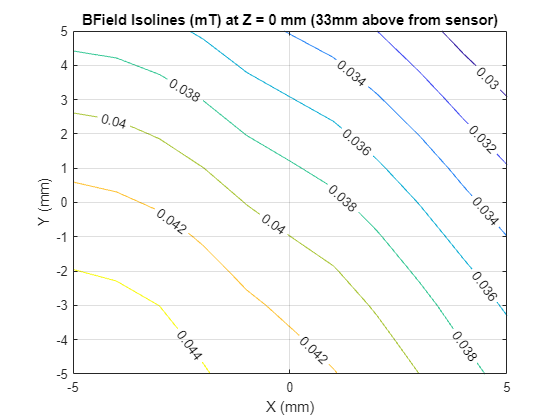

dataavg = [location sen1];
format longG
zzero = find(abs(dataavg(:,3)-0) < 0.1);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

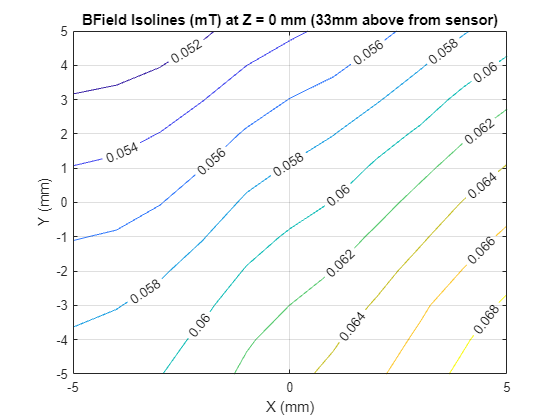


dataavg = [location sen2];
format longG
zzero = find(abs(dataavg(:,3)-0) < 0.1);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

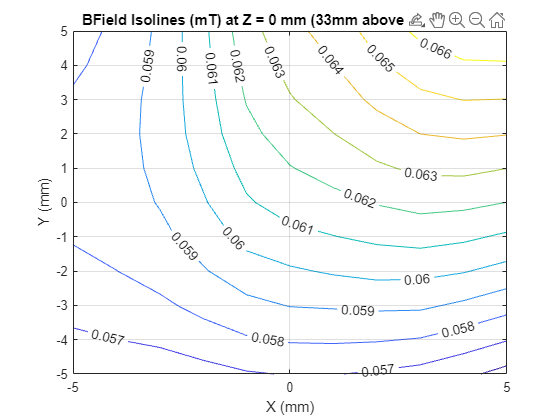


dataavg = [location sen3];
format longG
zzero = find(abs(dataavg(:,3)-0) < 0.1);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

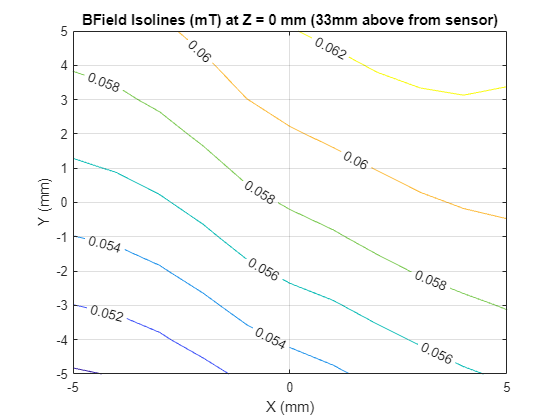


dataavg = [location sen4];
format longG
zzero = find(abs(dataavg(:,3)-0) < 0.1);

zzeromat = dataavg(zzero,:);
zeroB = sqrt(sum(zzeromat(:,4:5).^2,2));
zeroB = reshape(zeroB, [sqrt(121) sqrt(121)]);
zerox = reshape(zzeromat(:,1), [sqrt(121) sqrt(121)]);
zeroy = reshape(zzeromat(:,2), [sqrt(121) sqrt(121)]);

contour(zerox, zeroy, zeroB, 'ShowText', 'on')
hold on;
grid on;
title('BField Isolines (mT) at Z = 0 mm (33mm above from sensor)')
xlabel('X (mm)')
ylabel('Y (mm)')
hold off

function b = cost(v, B_data, B_t, size)
X1 = [-v(1) -v(2) -v(3)];
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], size, 1);
b = sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
end

function [c, ceq] = con(v)
c = [];
ceq = sqrt(sum([v(1) v(2) v(3)].^2, 2)) - 1;
end

function d = costd(v, loc, B_data, B_t, size)
X1 = [v(1) v(2) v(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], size, 1);
d = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function h = costh(v, loc, B_data, B_t, size)
X1 = -loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], size, 1);
h = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function s = costs(v, loc, B_data, B_t, size)
X1 = [v(1) v(2) v(3)] - loc;
R1 = sqrt(sum(X1.^2, 2));
H_0 = repelem([0 0 1], size, 1);
s = sum(sum((B_data - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2));
end

function m = multicost(v, sen1, sen2, sen3, sen4, B_t)
X1 = [0 0 -25] - [v(1) v(2) v(3)];
X2 = [-35 0 -25] - [v(1) v(2) v(3)];
X3 = [0 -35 -25] - [v(1) v(2) v(3)];
X4 = [-35 -35 -25] - [v(1) v(2) v(3)];
R1 = sqrt(sum(X1.^2, 2));
R2 = sqrt(sum(X2.^2, 2));
R3 = sqrt(sum(X3.^2, 2));
R4 = sqrt(sum(X4.^2, 2));
H_0 = repelem([0 0 1], 1, 1);

B1 = sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
B2 = sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2);
B3 = sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2);
B4 = sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2);
m = B1 + B2 + B3 + B4;
end

function a = multiangle(v, loc, sen1, sen2, sen3, sen4, B_t)
X1 = [0 0 -25] - loc;
X2 = [-35 0 -25] - loc;
X3 = [0 -35 -25] - loc;
X4 = [-35 -35 -25] - loc;
R1 = sqrt(sum(X1.^2, 2));
R2 = sqrt(sum(X2.^2, 2));
R3 = sqrt(sum(X3.^2, 2));
R4 = sqrt(sum(X4.^2, 2));
H_0 = repelem([v(1) v(2) v(3)], 1, 1);

B1 = sum((sen1 - B_t*(3*dot(H_0, X1, 2).*X1./R1.^5-H_0./R1.^3)).^2);
B2 = sum((sen2 - B_t*(3*dot(H_0, X2, 2).*X2./R2.^5-H_0./R2.^3)).^2);
B3 = sum((sen3 - B_t*(3*dot(H_0, X3, 2).*X3./R3.^5-H_0./R3.^3)).^2);
B4 = sum((sen4 - B_t*(3*dot(H_0, X4, 2).*X4./R4.^5-H_0./R4.^3)).^2);
a = B1 + B2 + B3 + B4;
end